# PCA figure for all calls with decision boundary of DFA

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType','MicAudioGood', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_AllCalls.mat'),  'NPC_opt_all', 'EigenVec_DFA_all', 'MPS_mic_wf', 'IndWf', 'MPS_mic_wt')

% Get the color vector ready for BatName, Sex and Deafness
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

%% Restrict the MPS spectral frequency to 3 cycles/kHz and normalized all
% MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';

Calculate again the PCA for all data (was not saved)

[PC,Score,~, ~, VarExpl,~] = pca(MPS_mic_norm);

Obtain a scatter plot of all calls in the first 2 PCA dimensions

Fig2 = figure(2);
clf
set(gcf,'Visible','on')
Slope = -EigenVec_DFA_all(1,1)/EigenVec_DFA_all(2,1);
Intercept = EigenVec_DFA_all(2,1);
% Canon = (Score(:,1:NPC_opt_all) - repmat(mean(Score(:,1:NPC_opt_all)),size(Score,1),1)) * EigenVec_DFA_all(:,1);
MicAudioGoodInd = find(MicAudioGood);
BatID_Mic = BatID(MicAudioGoodInd);
Legend=cell(length(BatName),1);
MKR = {'o', 's', 'd','o', 's','d', 'p','>', 'p','>'};
for bb=1:length(BatName)
    BatName_local = num2str(BatName(bb));
    Ind = strcmp(BatID_Mic, BatName_local);
    hold on
    Data_local = Score(Ind,1:2);
    IndRand = randperm(sum(Ind));
    Data_local = Data_local(IndRand(1:200),:)
    if contains(BatSexDeaf{bb}, 'D')
        s=scatter(Data_local(:,1), Data_local(:,2), 30, [0 0 0],MKR{bb},"filled");
    else
        s=scatter(Data_local(:,1), Data_local(:,2), 30, [0.7 0.7 0.7],MKR{bb},"filled");
    end
%     s.AlphaData = 0.2.*ones(size(Data_local,1),1);
%     s.MarkerFaceAlpha = 'flat';
    SepStr = strsplit(BatSexDeaf{bb});
    if strcmp(SepStr{1}(1), 'H')
        Legend{bb} = ['H' SepStr{2}(1) BatName_local(end)]; 
    else
        Legend{bb} = ['D' SepStr{2}(1) BatName_local(end)]; 
    end
end

Data_local =   -44.7771  -10.0005
   -8.9687   -9.6399
  -48.5333   -8.4402
   10.5672   -7.7011
  -30.9773   -4.6546
  -36.5157   -4.1687
  -41.0494  -11.1259
  -53.9158  -11.2621
  -36.3432   -8.3127
   40.6965    5.6744


Data_local =   -16.7695   -6.8350
   94.3627   -2.6660
  -41.6336  -12.2512
   24.3491   -4.7663
   35.1196   -6.6981
  -47.4806  -11.5766
  -40.3520  -16.5136
  -20.9096   -0.8161
   95.6722   -3.4046
  -53.7320  -16.3350


Data_local =   -25.3193  -10.0480
  -41.5849  -11.0135
  -30.8493   -8.1428
  -48.1235  -13.9023
   24.7978   21.0636
  -35.1051    0.4988
   38.5089   16.6874
   98.7996   -1.4083
  -44.3195  -15.1221
  -24.7494   -7.0228


Data_local =   -42.0003  -17.2474
  -30.0441  -14.4700
  -16.3706  -12.0490
   58.8776   -3.7536
  139.3797   -4.5636
   -6.4796   -9.1222
  -18.4471  -10.3050
   36.6471   -5.5647
  -30.9814  -11.9853
  -41.3622  -13.3740


Data_local =   -49.0293  -14.6665
   55.3160   -2.3926
  -51.4031  -16.1379
  121.5860    3.5106
  -35.6132  -11.6331
   37.6459  -11.5329
   22.7194    4.5105
  -11.0238   -9.4093
   50.9758    3.4264
  -43.6567  -11.5512


Data_local =   -33.0340   -8.1677
   28.0278   -8.6840
  -37.9367  -14.7215
  -42.6397   -2.2277
  -24.9337   -7.4390
    1.1814  -10.9308
  109.8255   -1.6582
  -42.5218   -9.9519
  -29.8256  -12.0700
    3.3982  -11.1968


Data_local =    51.9292    6.5944
  -36.5638  -15.0181
  -40.3690  -14.8982
   -9.8706   -8.2063
  -25.1269    1.3270
  116.5477    6.0801
  -47.0011  -15.4508
  -36.5164   -3.1465
   42.1461   -1.4946
  106.2828   -2.4982


Data_local =   138.6584   -0.0363
  -28.8830   54.1191
  -49.2293  -11.4825
   -6.5366   26.8514
   83.2838   -1.6072
   65.5219   -1.2040
  100.5917   -1.5856
  -42.3267  -14.9469
   -4.9985  -13.2144
  -34.2154   -2.2258


Data_local =   -38.7920   81.1224
   19.9612    9.4111
    1.1332    3.9808
   49.4029   -2.1005
  -29.3638   28.8468
    7.5631   21.0543
  -27.0233   -7.4025
  -26.9914  -12.8905
  -42.9867  -10.3145
   19.8993    0.4497


Data_local =   -33.6013   40.1226
  -38.3500   30.2361
   28.4706   -6.3674
  183.6484  -10.4771
  -29.5252  -11.8681
  -16.1666   -8.7723
   43.8831    1.7830
  -44.3044  -14.9179
  -28.7025  -14.5807
  -27.1620  -12.7108


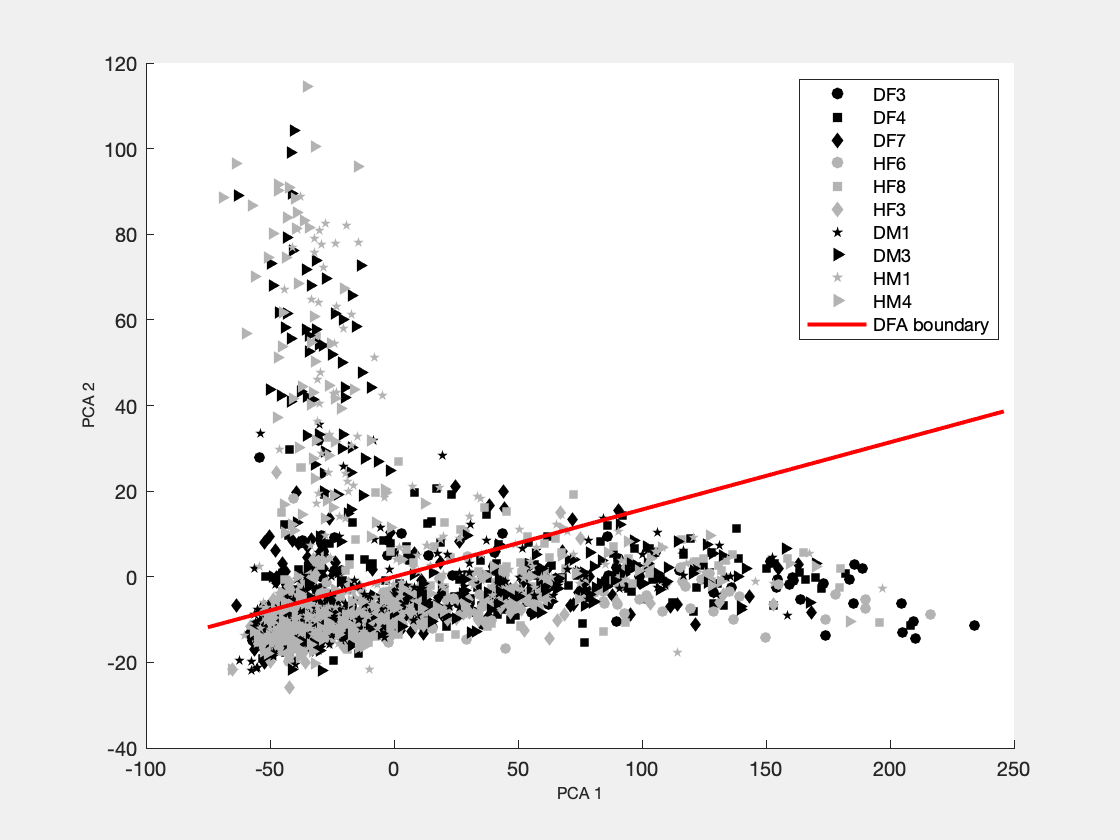

ylabel('PCA 2', 'FontSize',8);
xlabel('PCA 1', 'FontSize',8);

X=[min(Score(:,1)) max(Score(:,1))];
Y = Intercept + Slope.*X;
hold on
line(X,Y,'Color', 'r','LineWidth',2)
hold off
Legend{bb+1} = 'DFA boundary';
legend(Legend)

% ylim([-10 25])
% set(gca, 'XTick', 7:10,'XTickLabel', Legend(7:10), 'YTick', [-10 0 10 20],'YTickLabel',[-10 0 10 20], 'XLim', [6 11], 'FontSize',8)
% set(gca, 'Color', [0.9 0.9 0.9])

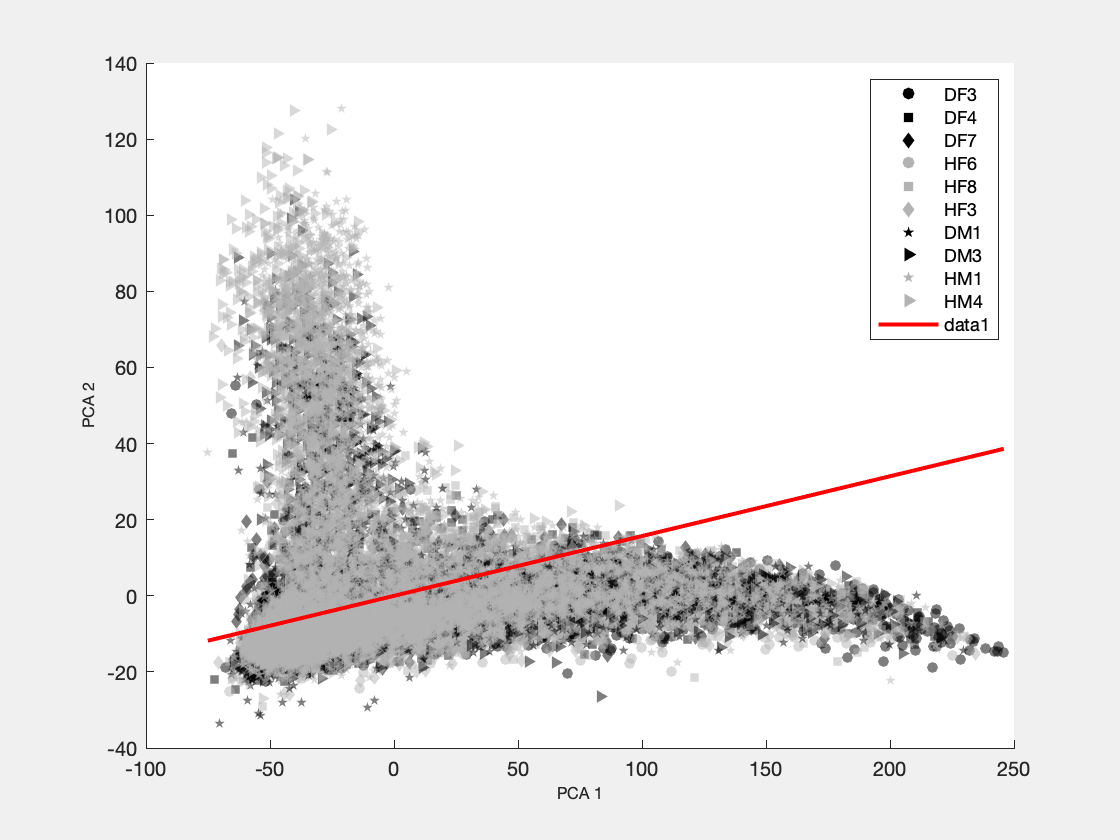

Fig2 = figure(2);
clf
set(gcf,'Visible','on')
Slope = -EigenVec_DFA_all(1,1)/EigenVec_DFA_all(2,1);
Intercept = EigenVec_DFA_all(2,1);


% Canon = (Score(:,1:NPC_opt_all) - repmat(mean(Score(:,1:NPC_opt_all)),size(Score,1),1)) * EigenVec_DFA_all(:,1);
MicAudioGoodInd = find(MicAudioGood);
BatID_Mic = BatID(MicAudioGoodInd);
Legend=cell(length(BatName),1);
MKR = {'o', 's', 'd','o', 's','d', 'p','>', 'p','>'};
for bb=1:length(BatName)
    BatName_local = num2str(BatName(bb));
    Ind = strcmp(BatID_Mic, BatName_local);
    hold on
    if contains(BatSexDeaf{bb}, 'D')
        s=scatter(Score(Ind,1), Score(Ind,2), 30, [0 0 0],MKR{bb},"filled");
    else
        s=scatter(Score(Ind,1), Score(Ind,2), 30, [0.7 0.7 0.7],MKR{bb},"filled");
    end
    s.AlphaData = 0.2.*ones(sum(Ind),1);
    s.MarkerFaceAlpha = 'flat';
    SepStr = strsplit(BatSexDeaf{bb});
    if strcmp(SepStr{1}(1), 'H')
        Legend{bb} = ['H' SepStr{2}(1) BatName_local(end)]; 
    else
        Legend{bb} = ['D' SepStr{2}(1) BatName_local(end)]; 
    end
end
ylabel('PCA 2', 'FontSize',8);
xlabel('PCA 1', 'FontSize',8);
legend(Legend)
X=[min(Score(:,1)) max(Score(:,1))];
Y = Intercept + Slope.*X;
hold on
line(X,Y,'Color', 'r','LineWidth',2)
hold off